m = 12;
l = 13;
g = 3.711;
K_P = 132.285;
K_D = 72;
K_I = 72;
CH = tf([K_D K_P K_I], [m 0 -g/l 0])

CH =
 
  72 s^2 + 132.3 s + 72
  ---------------------
    12 s^3 - 0.2855 s
 
Continuous-time transfer function.



% calc breakaway points
syms x
f = (K_P*x + K_I + K_D*x^2) / (m*x^3 - x*g/l);
vpa(solve(diff(f) == 0))

$$ans = \left(\begin{array}{c} 0.084381368032282405969655536294484\\ -0.094093223526127019882347053548972\\ -1.2310329928298417190756585164098\\ -2.433838485009647000344983299669 \end{array}\right)$$

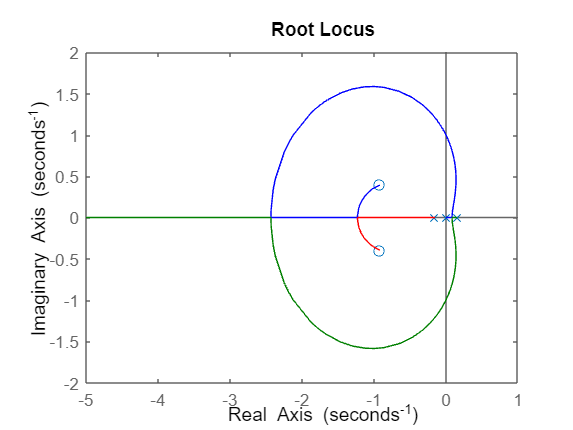

rlocus(CH)